clc;
clear

mycolor=zeros(3,202);

mycolor(1,:)=[0:0.01:1 zeros(1,101)+1];

mycolor(2,:)=[0:0.01:1 1:-0.01:0];

mycolor(3,:)=[zeros(1,101)+1 1:-0.01:0];

mycolor=mycolor';

data1 = load('data_60.mat');
data2 = load('data_68.mat');

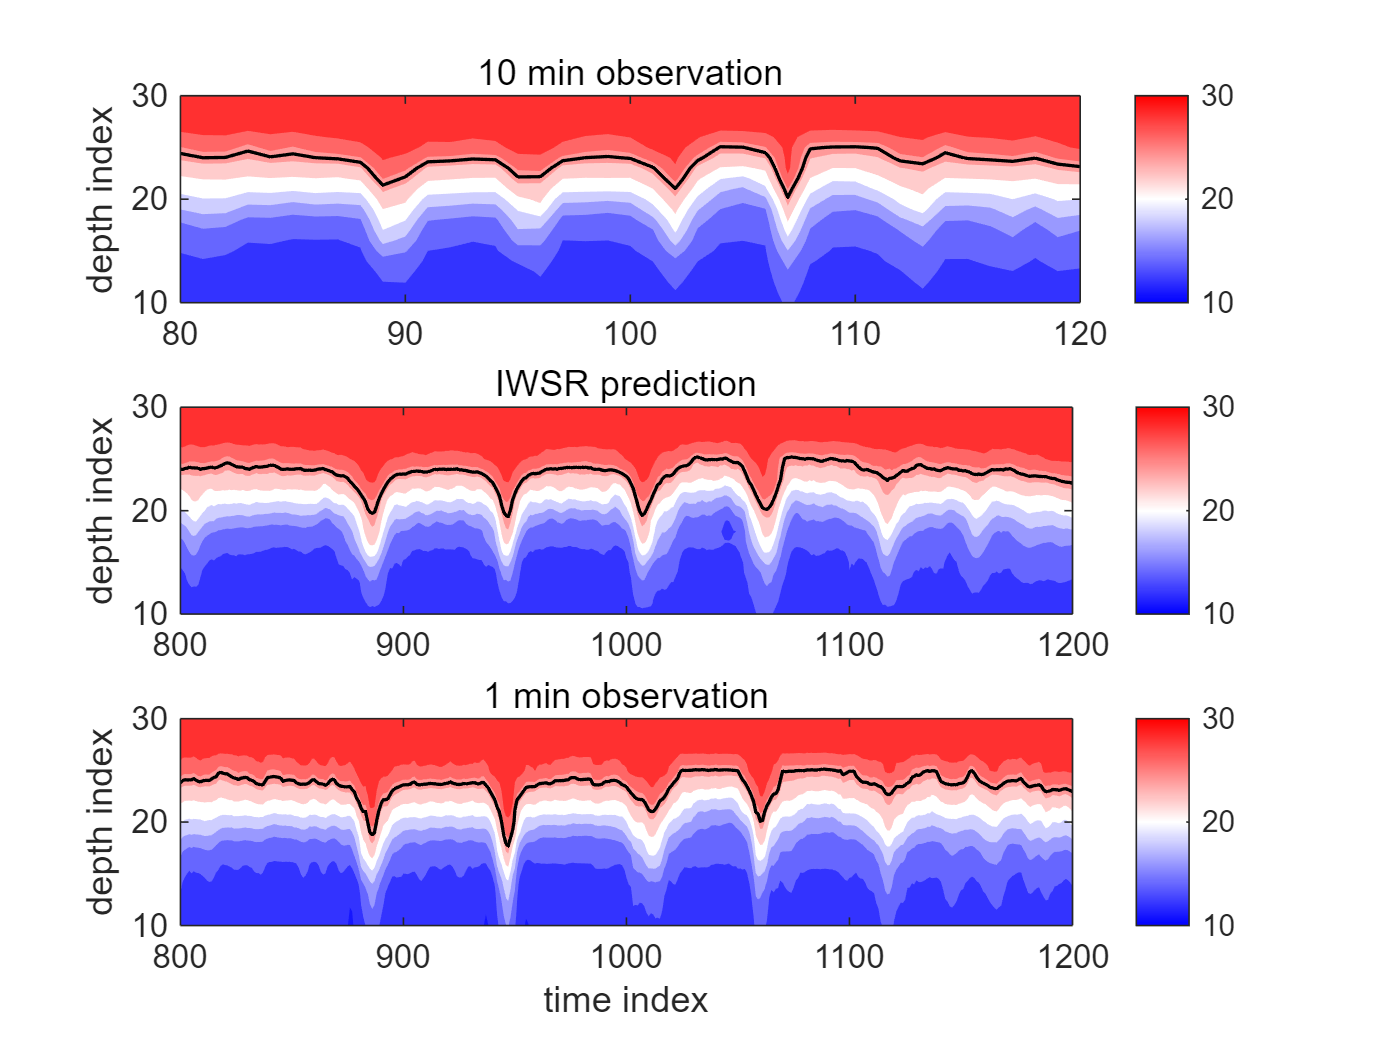


figure
subplot(3,1,1)
contourf(data1.inputs,'linewidth',0.5,'showtext','off','linestyle','none');%colorbar;
colormap(mycolor);colorbar;axis tight;
set(gca,'fontsize',10)
hold on
xlim([80,120])
ylim([10,30])
[C1,h] = contour(data1.inputs,[25,25],'k','linewidth',1);
caxis([10,30])

title('10 min observation')
ylabel('depth index')

subplot(3,1,2)
contourf(data1.pre,'linewidth',0.5,'showtext','off','linestyle','none');%colorbar;
colormap(mycolor);colorbar;axis tight;
set(gca,'fontsize',10)
hold on
xlim([800,1200])
ylim([10,30])
[C2,h] = contour(data1.pre,[25,25],'k','linewidth',1);
caxis([10,30])
title('IWSR prediction')
ylabel('depth index')
subplot(3,1,3)
contourf(data1.gt,'linewidth',0.5,'showtext','off','linestyle','none');%colorbar;
colormap(mycolor);colorbar;axis tight;
set(gca,'fontsize',10)
hold on
xlim([800,1200])
ylim([10,30])

[C3,h] = contour(data1.gt,[25,25],'k','linewidth',1);
caxis([10,30])

title('1 min observation')
xlabel('time index')
ylabel('depth index')

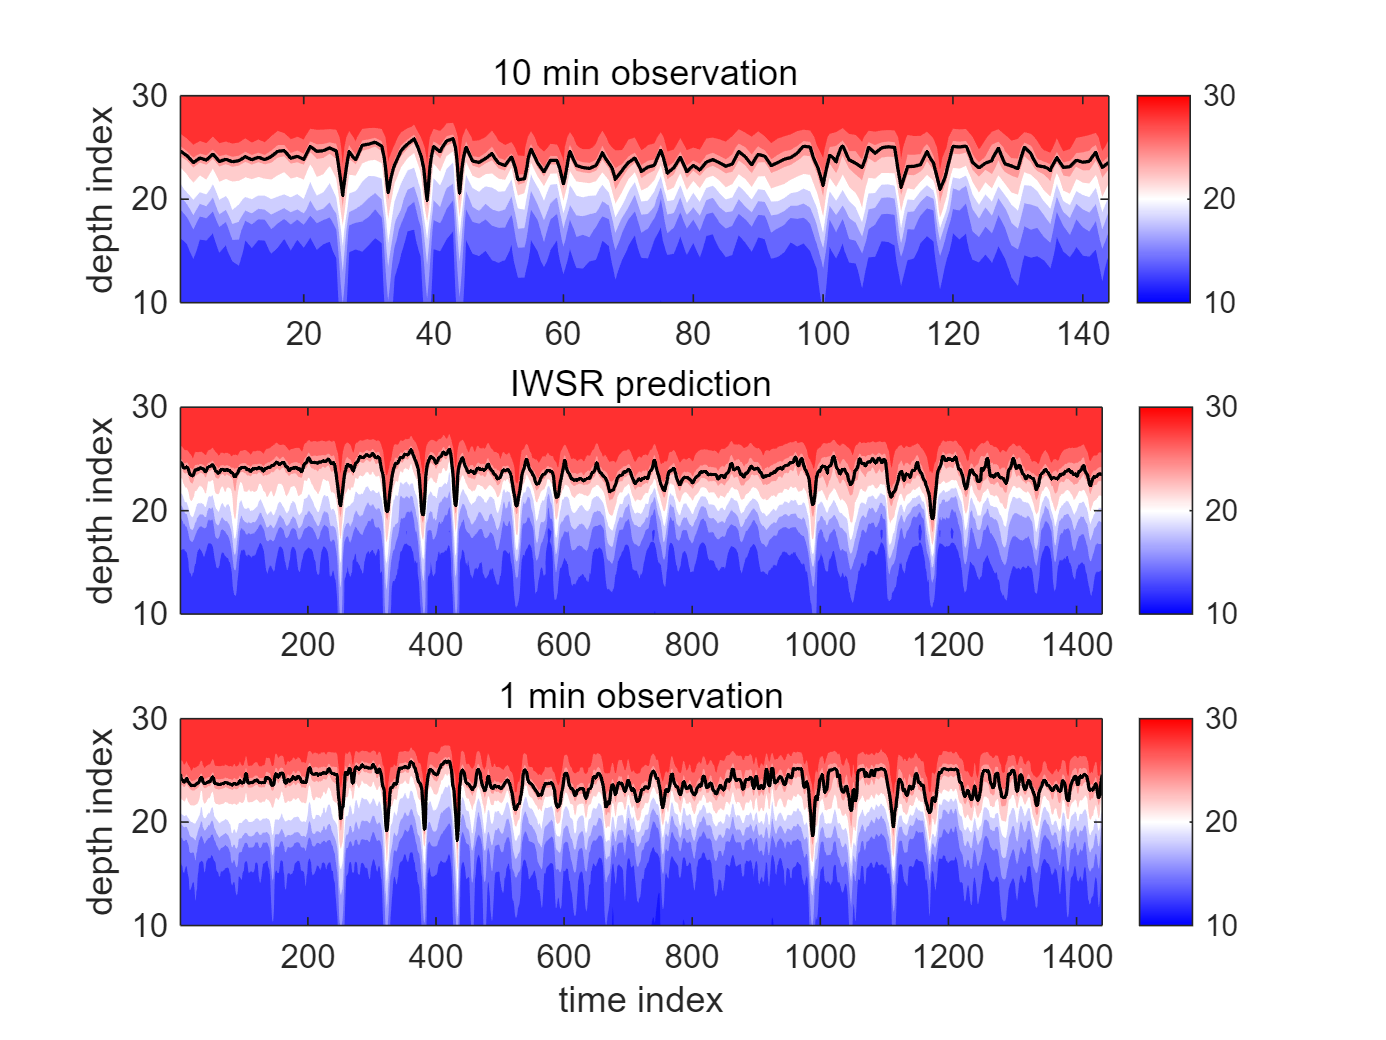



figure
subplot(3,1,1)
contourf(data2.inputs,'linewidth',0.5,'showtext','off','linestyle','none');%colorbar;
colormap(mycolor);colorbar;axis tight;
set(gca,'fontsize',10)
hold on
ylim([10,30])
[C1,h] = contour(data2.inputs,[25,25],'k','linewidth',1);
caxis([10,30])

title('10 min observation')
ylabel('depth index')

subplot(3,1,2)
contourf(data2.pre,'linewidth',0.5,'showtext','off','linestyle','none');%colorbar;
colormap(mycolor);colorbar;axis tight;
set(gca,'fontsize',10)
hold on
ylim([10,30])
[C2,h] = contour(data2.pre,[25,25],'k','linewidth',1);
caxis([10,30])
title('IWSR prediction')
ylabel('depth index')


subplot(3,1,3)
contourf(data2.gt,'linewidth',0.5,'showtext','off','linestyle','none');%colorbar;
colormap(mycolor);colorbar;axis tight;
set(gca,'fontsize',10)
hold on
ylim([10,30])

[C3,h] = contour(data2.gt,[25,25],'k','linewidth',1);
caxis([10,30])

title('1 min observation')
xlabel('time index')
ylabel('depth index')